## １２：筋肉組織の音速以上になっている経路に関してRFデータを参照する．

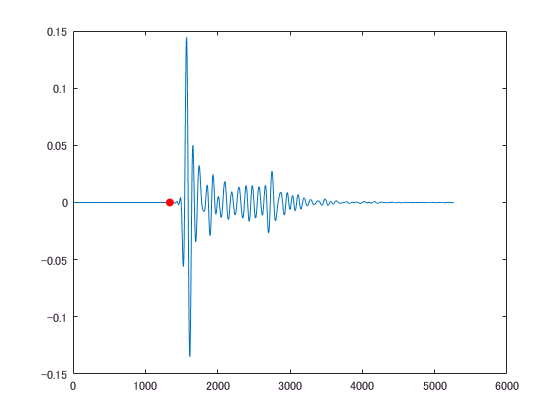

clear;
load("H:\data\kwave\result\2018_10_15_realisticScatter_variousIMCL_Correct\EMCL_num_75\statistics.mat")
% movieで目視して72番目のサンプルが筋肉組織以上の音速になっていることが顕著に現れていたため，７２番目のサンプルについてのRFデータを参照する．
load("H:\data\kwave\result\2018_10_15_realisticScatter_variousIMCL_Correct\case72_IMCL0.2\rfdata.mat")
load("H:\data\kwave\result\2018_10_15_realisticScatter_variousIMCL_Correct\case72_IMCL0.2\kgrid.mat")
load("H:\data\configration\transducer_2board.mat")
rfdata_72 = rfdata;
transimit_fastest = ind_fastest(1,1,72);
receive_fastest = ind_fastest(2,1,72);
figure;
plot(rfdata_72(:,100+receive_fastest,transimit_fastest));
hold on
scatter(tof_cell(100+receive_fastest,transimit_fastest,72,1)/kgrid.dt,0,'filled','red');

一見合っているように見えるけれど...

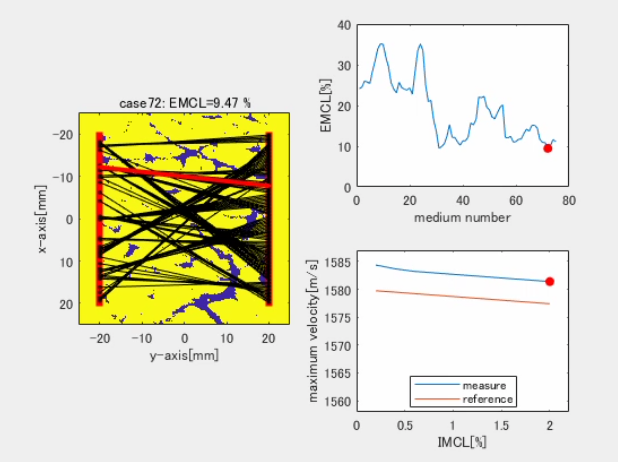

そもそも時間サンプル点を一つずらして誤検出してしまった場合，誤差はどれだけになるだろうか．

norm(t_pos(:,transimit_fastest)-t_pos(:,receive_fastest+100))/tof_cell(100+receive_fastest,transimit_fastest,72,1)

ans = 1.5846e+03

norm(t_pos(:,transimit_fastest)-t_pos(:,receive_fastest+100))/(tof_cell(100+receive_fastest,transimit_fastest,72,1)+kgrid.dt)

ans = 1.5834e+03

40e-3 / (2.531e-05)

ans = 1.5804e+03

40e-3 / (2.531e-05 + kgrid.dt)

ans = 1.5792e+03

時間サンプルを１つずらして誤検出してしまった場合，音速が１m/sだけずれる．

しきい値法では時間サンプル検出誤差が５サンプル分ほど発生してしまうことがわかった．

しきい値法をいくら校正したところで，誤差が大きいことは免れない可能性が高い．

## １３：相互相関法を用いてみる

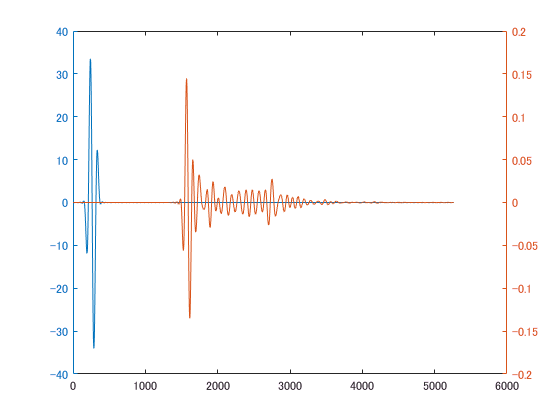

load("H:\data\kwave\result\2018_10_15_realisticScatter_variousIMCL_Correct\case72_IMCL0.2\sourse_wave.mat")
figure;
yyaxis left
plot(source_wave);
ylim([-40 40])
hold on 
yyaxis right
plot(rfdata_72(:,100+receive_fastest,transimit_fastest))
ylim([-0.2 0.2])

[acor,lag] = xcorr(rfdata_72(:,100+receive_fastest,transimit_fastest),source_wave);
[~,I] = max(abs(acor));
lagDiff = lag(I) + 12.3

lagDiff = 1.3393e+03

lagDiff * kgrid.dt

ans = 2.5434e-05

norm(t_pos(:,transimit_fastest)-t_pos(:,receive_fastest+100)) / (lagDiff * kgrid.dt)

ans = 1.5842e+03

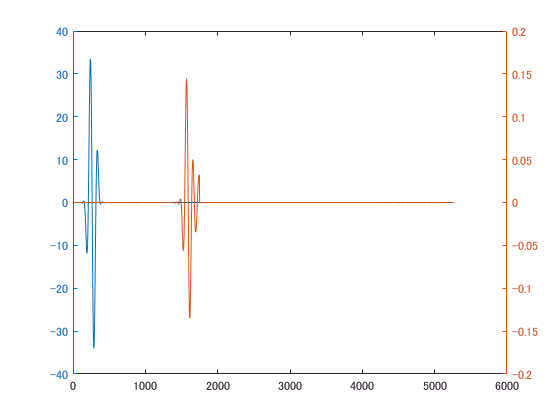

load("H:\data\kwave\result\2018_10_15_realisticScatter_variousIMCL_Correct\case72_IMCL0.2\sourse_wave.mat")
figure;
yyaxis left
plot(source_wave);
ylim([-40 40])
hold on 
yyaxis right
rfdata_72(1750:end,100+receive_fastest,transimit_fastest) = 0;
plot(rfdata_72(:,100+receive_fastest,transimit_fastest))
ylim([-0.2 0.2])

[acor,lag] = xcorr(rfdata_72(:,100+receive_fastest,transimit_fastest),source_wave);
[~,I] = max(abs(acor));
lagDiff = lag(I) + 12.3

lagDiff = 1.3393e+03

lagDiff * kgrid.dt

ans = 2.5434e-05

norm(t_pos(:,transimit_fastest)-t_pos(:,receive_fastest+100)) / (lagDiff * kgrid.dt)

ans = 1.5842e+03

相互相関法を用いてみても，しきい値法と同程度に速度が大きく算出されてしまった．

1580 m/s以内に収まった．筋肉組織だけの媒質データでも検証してみる．（見間違い）

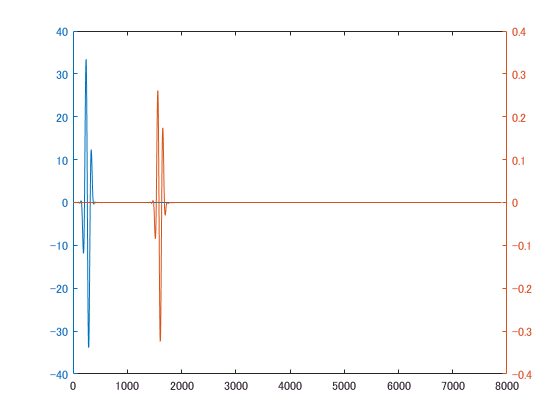

load("H:\data\kwave\result\2018_09_11_no_object_variousFrequency\freq500_valid\rfdata.mat")
load("H:\data\kwave\result\2018_09_11_no_object_variousFrequency\freq500_valid\kgrid.mat")
load("H:\data\kwave\result\2018_09_11_no_object_variousFrequency\freq500_valid\sourse_wave.mat")
rfdata_no_object = rfdata;
figure;
yyaxis left
plot(source_wave);
ylim([-40 40])
hold on 
yyaxis right
plot(rfdata_no_object(:,101));
ylim([-0.4 0.4])

[acor,lag] = xcorr(rfdata_no_object(:,101),source_wave);
[~,I] = max(abs(acor));
lagDiff = lag(I) + 12.3

lagDiff = 1.3333e+03

lagDiff * kgrid.dt

ans = 2.5316e-05

norm(t_pos(:,101)-t_pos(:,1)) / (lagDiff * kgrid.dt)

ans = 1.5800e+03

オフセットを入れて校正する手順もしきい値法と同じ．

load("H:\data\kwave\result\2018_10_15_realisticScatter_variousIMCL_Correct\case72_IMCL0.2\sourse_wave.mat")
source_wave2 = source_wave;
load("H:\data\kwave\result\2018_09_11_no_object_variousFrequency\freq500_valid\sourse_wave.mat")
source_wave1 = source_wave;
[acor,lag] = xcorr(source_wave2,source_wave1);
[max_acor,I] = max(abs(acor))

max_acor = 6.4260e+04

I = 7901

lag(I)

ans = 0

ch1の送信素子からの信号を同じくch1で受信したときのRFデータとsource_waveとの差を調べる．

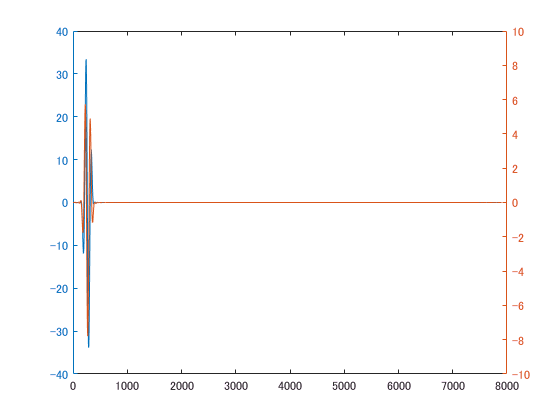

figure;
yyaxis left
plot(source_wave1);
ylim([-40 40])
hold on
yyaxis right
plot(rfdata_no_object(:,1));
ylim([-10 10])

source_waveと，同一素子での送受信波との形はかなり異なる．

後者を基準とした相互相関をとってみる．

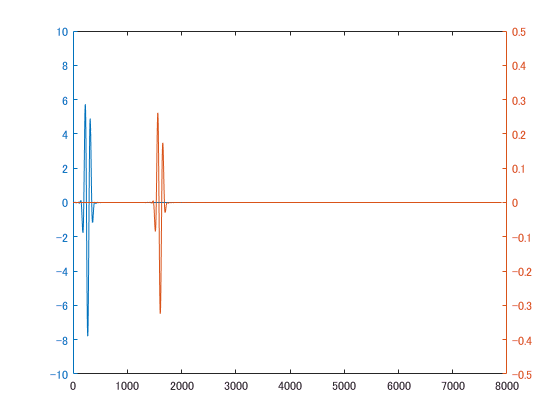

figure;
yyaxis left
plot(rfdata_no_object(:,1));
ylim([-10 10])
hold on
yyaxis right
plot(rfdata_no_object(:,101));
ylim([-0.5 0.5])

[acor,lag] = xcorr(rfdata_no_object(:,101),rfdata_no_object(:,1));
[max_acor,I] = max(abs(acor))

max_acor = 119.1951

I = 9238

lagDiff = lag(I) -3.7

lagDiff = 1.3333e+03

lagDiff * kgrid.dt

ans = 2.5316e-05

norm(t_pos(:,101)-t_pos(:,1)) / (lagDiff * kgrid.dt)

ans = 1.5800e+03

この校正法でcase72について適用してみる．

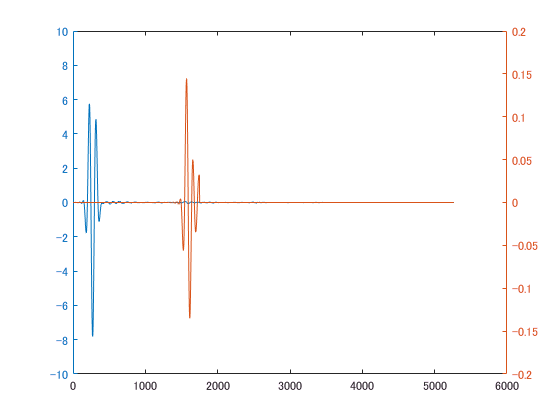

load("H:\data\kwave\result\2018_10_15_realisticScatter_variousIMCL_Correct\case72_IMCL0.2\rfdata.mat")
figure;
yyaxis left
plot(rfdata_72(:,transimit_fastest,transimit_fastest));
ylim([-10 10])
hold on 
yyaxis right
plot(rfdata_72(:,100+receive_fastest,transimit_fastest))
ylim([-0.2 0.2])

[acor,lag] = xcorr(rfdata_72(:,100+receive_fastest,transimit_fastest),rfdata_72(:,transimit_fastest,transimit_fastest));
[max_acor,I] = max(abs(acor))

max_acor = 51.5938

I = 6609

lagDiff = lag(I) -3.7

lagDiff = 1.3393e+03

lagDiff * kgrid.dt

ans = 2.5430e-05

norm(t_pos(:,transimit_fastest)-t_pos(:,receive_fastest+100)) / (lagDiff * kgrid.dt)

ans = 1.5845e+03